# Deep Learning Classification

Author: Ethan L. Edmunds

clc; clear; close all

## 1 Load Image Data

% Define image folder name
imageFolder = "defect_dataset";

% Collect data from image folder
imds = imageDatastore(imageFolder, "IncludeSubfolders", true, "LabelSource", "foldernames");

% Show the number of each type of class
tbl_count = countEachLabel(imds)

tbl_count = 4×2 table
         Label         Count
    _______________    _____

    crack              1807 
    lack of fusion      900 
    pore               1830 
    pore with crack     263 


totalImgCount = sum(tbl_count{:,"Count"}) % Print the total number of defects found

totalImgCount = 4800

% Preview one of each class
crack_preview = find(imds.Labels == 'Crack', 1);
pore_preview = find(imds.Labels == 'Pore', 1);
poreWithCrack_preview = find(imds.Labels == 'Pore with Crack', 1);
lackOfFusion_preview = find(imds.Labels == 'Lack of Fusion', 1);

## 2 Training, Validation and Test dataset creation

% Create training, validation, and test datasets
[imdsTrain, imdsVal] = splitEachLabel(imds, 0.7, 0.3, "randomized");

tbl_count = countEachLabel(imdsTrain)

tbl_count = 4×2 table
         Label         Count
    _______________    _____

    crack              1265 
    lack of fusion      630 
    pore               1281 
    pore with crack     184 


tbl_count = countEachLabel(imdsVal)

tbl_count = 4×2 table
         Label         Count
    _______________    _____

    crack               542 
    lack of fusion      270 
    pore                549 
    pore with crack      79 


## 3 Image Augmentation

% Specifies preprocessing options for image augmentation, such as resizing,
% rotation, translation and reflection.

% Randomly translate the images up to three pixels horizontally and
% vertically, rotate the images with an angle up to 20 degrees
imageAugmenter = imageDataAugmenter( ...
    RandXReflection=true, ...
    RandYReflection=true, ...
    RandRotation=[-180 180]);

% Define image size
imageSize = [200 200];
imdsTrain_aug = augmentedImageDatastore(imageSize, imdsTrain, "DataAugmentation", imageAugmenter);
imdsVal_aug = augmentedImageDatastore(imageSize, imdsVal, "DataAugmentation", imageAugmenter);

% Create array of labels for model evaluation
YVal = categorical(imdsVal.Labels);

minibatch = read(imdsTrain_aug);
imshow(imtile(minibatch.input))

## 4 Design Deep Neural Network (Baseline)

% Define constant parameters
num_classes = 4;
num_filters = 26;
filter_size = 10;

% Auxiliary parameters
aux_params{1} = num_classes;
aux_params{2} = imageSize;

% Define network layers
baseline_layers = [
    imageInputLayer([imageSize 1])

    % block 1 %
    convolution2dLayer(filter_size,num_filters,"Padding","same");
    batchNormalizationLayer;
    reluLayer;
    maxPooling2dLayer(2,'Stride',2);

    % block 2 %
    convolution2dLayer(filter_size,num_filters,"Padding","same");
    batchNormalizationLayer;
    reluLayer;
    maxPooling2dLayer(2,'Stride',2);

    % block 3 %
    convolution2dLayer(filter_size,num_filters,"Padding","same");
    batchNormalizationLayer;
    reluLayer;
    maxPooling2dLayer(2,'Stride',2);

    % block 4 %
    convolution2dLayer(filter_size,num_filters,"Padding","same");
    batchNormalizationLayer;
    reluLayer;
    maxPooling2dLayer(2,'Stride',2);

    % block 5 %
    convolution2dLayer(filter_size,num_filters,"Padding","same");
    batchNormalizationLayer;
    reluLayer;
    maxPooling2dLayer(2,'Stride',2);

    % block 6 %
    convolution2dLayer(filter_size,num_filters,"Padding","same");
    batchNormalizationLayer;
    reluLayer;
    maxPooling2dLayer(2,'Stride',2);

    % block 7 %
    convolution2dLayer(filter_size,num_filters,"Padding","same");
    batchNormalizationLayer;
    reluLayer;
    maxPooling2dLayer(2,'Stride',2);

    % block 8 %
    convolution2dLayer(filter_size,num_filters,"Padding","same");
    batchNormalizationLayer;
    reluLayer;
    maxPooling2dLayer(2,'Stride',2);
    
    dropoutLayer(0.3)

    fullyConnectedLayer(num_classes)
    softmaxLayer
    classificationLayer];

% Display the network design
% analyzeNetwork(baseline_layers);

% Disable pop-up window while training
net.trainParam.showWindow = 0; 

% Training options
baseline_options = trainingOptions('adam', ...
    "MiniBatchSize",30, ...
    'InitialLearnRate',0.002, ...
    'MaxEpochs',10, ...
    'Shuffle','every-epoch', ...
    'ValidationData',imdsVal_aug, ...
    'ValidationFrequency',10, ...
    'Verbose',true, ...
    'Plots','training-progress', ...
    'ExecutionEnvironment', 'gpu');

## 4.1 Neural Network Training

tic; % Start timer
disp ("Training Neural Network...")

Training Neural Network...


[baseline_model, baseline_model_info] = trainNetwork(imdsTrain_aug, baseline_layers, baseline_options)

Error using trainNetwork (line 191)
Invalid network.

Caused by:
    Layer 33: The size of the pooling dimensions of the padded input data must be larger than or equal to the pool size. For networks with sequence input, this check depends on the MinLength property of the sequence input layer. To ensure that this check is accurate, set MinLength to the shortest sequence length of your training data.

baseline_training_time = toc % Stop timing after training
% saveas(gcf,'baselineModel_training.png')
clear tic;

## 4.2 Evaluation of baseline neural network

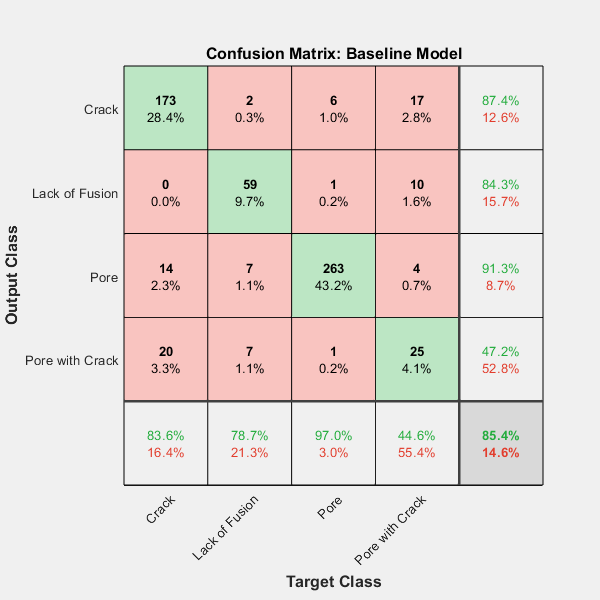

% classify the validation output using the trained network
[baseline_YPred, ~] = classify(baseline_model, imdsVal_aug);

% Plot confusion matrixa
figure;
plotconfusion(YVal, baseline_YPred);
title("Confusion Matrix: Baseline Model")
saveas(gcf,'baselineModel_eval.png')

## 5 Implement and evaluate effects of using 'Grid Search'

n = size(imdsTrain.Files, 1);
ind = randsample(1:n, totalImgCount*0.3);
subsetTrain = subset(imdsTrain, ind);

countEachLabel(subsetTrain)

ans = 4×2 table
         Label         Count
    _______________    _____

    Crack               211 
    Lack of Fusion       80 
    Pore                257 
    Pore with Crack      61 


subsetTrain_aug = augmentedImageDatastore(imageSize, subsetTrain);

% Define the grid of hyperparameters
num_layers = [3, 4, 5, 6]; % number of layers
num_filters = [10, 15, 20, 25, 30]; % number of filters per layer
gridsearch_best_accuracy = 0;
gridsearch_accuracy = zeros(length(num_layers), length(num_filters)); % preallocating memory

gridsearch_options = trainingOptions('adam', ...
    "MiniBatchSize", 16, ...
    'InitialLearnRate',0.002, ...
    'MaxEpochs', 7, ...
    'Shuffle','every-epoch', ...
    'ValidationData', imdsVal_aug, ...
    'ValidationFrequency',8, ...
    'Verbose',true);

### 5.1 Design deep neural network

% Loop over the grid of hyperparameters
tic
for i = 1:length(num_layers)
    for j = 1:length(num_filters)
    % Current hyperparameters
    hyper_params = [num_layers(i), num_filters(j)];

    % Create and train model with current hyperparams
    gridsearch_layers = create_model(hyper_params, aux_params);

    % Train model
    str = "Number filters: " + num_filters(j) + " | " + "Number layers: " + num_layers(i);
    disp(str);
    [model,info] = trainNetwork(subsetTrain_aug, gridsearch_layers, gridsearch_options);
    close(findall(groot, 'Tag', 'NNET_CNN_TAININGPLOT_UIFIGURE'));

    % Extract validation accuracy for current model
    gridsearch_accuracy(i,j) = info.ValidationAccuracy(end);

    % Store parameters if they are better than previous
    if gridsearch_accuracy(i,j) > gridsearch_best_accuracy
        gridsearch_best_accuracy = gridsearch_accuracy(i, j);
        gridsearch_best_params = hyper_params;
    end
    end
end

Number filters: 10 | Number layers: 3


Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:00 |       25.00% |       61.90% |       2.3680 |       3.7266 |          0.0020 |
|       1 |           8 |       00:00:02 |       25.00% |       26.60% |       4.3536 |       4.5191 |          0.0020 |
|       1 |          16 |       00:00:03 |       75.00% |       71.92% |       1.7258 |       2.1419 |          0.0020 |
|       1 |          24 |       00:00:04 |       93.75% |       67.49% |       0.3066 |   

Number filters: 15 | Number layers: 3


Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:01 |       12.50% |       66.34% |       2.1707 |       4.1527 |          0.0020 |
|       1 |           8 |       00:00:02 |       50.00% |       74.55% |       4.5575 |       2.3555 |          0.0020 |
|       1 |          16 |       00:00:04 |       81.25% |       73.40% |       0.4992 |       1.2096 |          0.0020 |
|       1 |          24 |       00:00:06 |       75.00% |       76.68% |       1.0873 |   

Number filters: 20 | Number layers: 3


Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:01 |       31.25% |       18.23% |       1.8855 |       9.3513 |          0.0020 |
|       1 |           8 |       00:00:03 |       56.25% |       54.35% |       3.1523 |       2.2980 |          0.0020 |
|       1 |          16 |       00:00:05 |       62.50% |       62.07% |       1.6235 |       1.9435 |          0.0020 |
|       1 |          24 |       00:00:07 |       75.00% |       76.03% |       1.8906 |   

Number filters: 25 | Number layers: 3


Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:01 |       18.75% |       33.99% |       2.4008 |      16.7385 |          0.0020 |
|       1 |           8 |       00:00:03 |        6.25% |       61.58% |       7.1694 |       2.3622 |          0.0020 |
|       1 |          16 |       00:00:06 |       62.50% |       65.52% |       6.9542 |       4.1784 |          0.0020 |
|       1 |          24 |       00:00:08 |       75.00% |       65.19% |       2.5221 |   

Number filters: 30 | Number layers: 3


Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:01 |       31.25% |       50.57% |       2.0782 |      12.6627 |          0.0020 |
|       1 |           8 |       00:00:04 |       43.75% |       64.04% |       8.7687 |       4.1876 |          0.0020 |
|       1 |          16 |       00:00:06 |       75.00% |       64.20% |       1.2040 |       1.7522 |          0.0020 |
|       1 |          24 |       00:00:09 |       68.75% |       72.41% |       1.1327 |   

Number filters: 10 | Number layers: 4


Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:01 |       25.00% |       33.33% |       1.9555 |       1.5858 |          0.0020 |
|       1 |           8 |       00:00:02 |       56.25% |       66.17% |       1.4522 |       1.1085 |          0.0020 |
|       1 |          16 |       00:00:03 |       43.75% |       54.02% |       1.4281 |       1.1106 |          0.0020 |
|       1 |          24 |       00:00:05 |       62.50% |       73.23% |       1.3211 |   

Number filters: 15 | Number layers: 4


Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:01 |       50.00% |       39.74% |       1.8185 |       2.5592 |          0.0020 |
|       1 |           8 |       00:00:02 |       56.25% |       69.13% |       1.4126 |       1.0717 |          0.0020 |
|       1 |          16 |       00:00:04 |       50.00% |       63.71% |       1.2605 |       1.1128 |          0.0020 |
|       1 |          24 |       00:00:05 |       56.25% |       77.18% |       0.8070 |   

Number filters: 20 | Number layers: 4


Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:01 |       12.50% |       26.11% |       1.7205 |       3.4975 |          0.0020 |
|       1 |           8 |       00:00:03 |       37.50% |       60.26% |       3.2062 |       1.7076 |          0.0020 |
|       1 |          16 |       00:00:05 |       62.50% |       68.47% |       0.9287 |       1.0627 |          0.0020 |
|       1 |          24 |       00:00:06 |       93.75% |       71.76% |       0.2705 |   

Number filters: 25 | Number layers: 4


Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:01 |       12.50% |       33.99% |       1.9364 |       4.6652 |          0.0020 |
|       1 |           8 |       00:00:04 |       87.50% |       67.32% |       1.4079 |       1.4530 |          0.0020 |
|       1 |          16 |       00:00:06 |       56.25% |       72.58% |       1.1927 |       1.2541 |          0.0020 |
|       1 |          24 |       00:00:09 |       81.25% |       78.65% |       0.7015 |   

Number filters: 30 | Number layers: 4


Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:01 |       18.75% |       44.50% |       1.8902 |       6.1328 |          0.0020 |
|       1 |           8 |       00:00:04 |       75.00% |       67.82% |       0.7055 |       1.2777 |          0.0020 |
|       1 |          16 |       00:00:06 |       62.50% |       63.88% |       1.8120 |       1.2729 |          0.0020 |
|       1 |          24 |       00:00:09 |       68.75% |       79.47% |       1.1190 |   

Number filters: 10 | Number layers: 5


Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:01 |       62.50% |       45.65% |       1.4720 |       1.6064 |          0.0020 |
|       1 |           8 |       00:00:02 |       81.25% |       60.43% |       0.6192 |       1.0089 |          0.0020 |
|       1 |          16 |       00:00:04 |       56.25% |       66.83% |       0.8733 |       0.8337 |          0.0020 |
|       1 |          24 |       00:00:05 |       75.00% |       73.07% |       0.9483 |   

Number filters: 15 | Number layers: 5


Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:01 |       12.50% |       40.56% |       1.9832 |       1.4511 |          0.0020 |
|       1 |           8 |       00:00:02 |       68.75% |       65.52% |       0.7493 |       0.8954 |          0.0020 |
|       1 |          16 |       00:00:04 |       87.50% |       74.06% |       0.6486 |       0.6701 |          0.0020 |
|       1 |          24 |       00:00:06 |       75.00% |       78.82% |       0.9514 |   

Number filters: 20 | Number layers: 5


Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:01 |        6.25% |       47.45% |       2.6282 |       1.3669 |          0.0020 |
|       1 |           8 |       00:00:03 |       75.00% |       67.82% |       0.9570 |       1.0304 |          0.0020 |
|       1 |          16 |       00:00:05 |       56.25% |       69.13% |       0.9883 |       0.7444 |          0.0020 |
|       1 |          24 |       00:00:07 |       93.75% |       78.49% |       0.1989 |   

Number filters: 25 | Number layers: 5


Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:01 |       37.50% |       46.14% |       1.6413 |       1.7759 |          0.0020 |
|       1 |           8 |       00:00:04 |       75.00% |       66.01% |       0.9090 |       0.9525 |          0.0020 |
|       1 |          16 |       00:00:06 |       87.50% |       76.85% |       0.3870 |       0.6724 |          0.0020 |
|       1 |          24 |       00:00:09 |       75.00% |       78.33% |       0.5330 |   

Number filters: 30 | Number layers: 5


Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:01 |       37.50% |       46.47% |       1.5747 |       2.1050 |          0.0020 |
|       1 |           8 |       00:00:04 |       50.00% |       60.26% |       1.1039 |       0.9158 |          0.0020 |
|       1 |          16 |       00:00:06 |       43.75% |       75.86% |       0.9464 |       0.6764 |          0.0020 |
|       1 |          24 |       00:00:09 |       81.25% |       81.77% |       0.6044 |   

Number filters: 10 | Number layers: 6


Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:01 |        0.00% |       11.66% |       3.8377 |       2.4177 |          0.0020 |
|       1 |           8 |       00:00:02 |       62.50% |       61.25% |       1.4189 |       1.1010 |          0.0020 |
|       1 |          16 |       00:00:04 |       81.25% |       68.97% |       0.6813 |       0.9829 |          0.0020 |
|       1 |          24 |       00:00:05 |       56.25% |       68.97% |       1.2609 |   

Number filters: 15 | Number layers: 6


Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:01 |        6.25% |       14.45% |       3.2827 |       2.1101 |          0.0020 |
|       1 |           8 |       00:00:02 |       43.75% |       63.05% |       1.4082 |       1.0615 |          0.0020 |
|       1 |          16 |       00:00:04 |       87.50% |       71.10% |       0.5802 |       0.8007 |          0.0020 |
|       1 |          24 |       00:00:06 |       68.75% |       75.70% |       0.7074 |   

Number filters: 20 | Number layers: 6


Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:01 |        6.25% |       33.66% |       2.0426 |       1.6824 |          0.0020 |
|       1 |           8 |       00:00:03 |       37.50% |       65.68% |       1.2919 |       0.8874 |          0.0020 |
|       1 |          16 |       00:00:05 |       62.50% |       70.28% |       0.9088 |       0.8272 |          0.0020 |
|       1 |          24 |       00:00:07 |       68.75% |       76.85% |       0.7108 |   

Number filters: 25 | Number layers: 6


Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:01 |       18.75% |       44.66% |       1.7874 |       1.5554 |          0.0020 |
|       1 |           8 |       00:00:04 |       81.25% |       68.31% |       0.6331 |       0.9260 |          0.0020 |
|       1 |          16 |       00:00:06 |       56.25% |       71.26% |       1.0514 |       0.7408 |          0.0020 |
|       1 |          24 |       00:00:09 |       81.25% |       80.95% |       0.5131 |   

Number filters: 30 | Number layers: 6


Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:01 |       18.75% |       55.67% |       2.0513 |       1.3690 |          0.0020 |
|       1 |           8 |       00:00:04 |       50.00% |       73.56% |       1.1171 |       0.7373 |          0.0020 |
|       1 |          16 |       00:00:07 |       75.00% |       77.67% |       0.7695 |       0.6486 |          0.0020 |
|       1 |          24 |       00:00:09 |       87.50% |       79.64% |       0.3105 |   

gridsearch_training_time = toc

gridsearch_training_time = 1.4888e+03

gridsearch_accuracy

gridsearch_accuracy =    80.6240   78.9819   83.5796   82.4302   79.9672
   84.0722   82.9228   85.8785   85.3859   83.9080
   84.0722   87.3563   83.4154   86.5353   85.5501
   83.7438   86.0427   78.6535   83.5796   85.3859


## 5.2 Show graphically variation of accuracy with filters and layers 

% Show best parameters
gridsearch_best_params

gridsearch_best_params =      5    15



% Create array for strings for label in graph
gridsearch_legend = string(num_layers);

% Plot the variation of accuracy with number of filters and number of
% layers
figure;
hold on
for i = 1:length(num_layers)
    plot(num_filters, gridsearch_accuracy(i,:), "LineWidth", 1);
end
xlabel('Number of filters')
ylabel('Accuracy')
xlim([min(num_filters) max(num_filters)])
% ylim([0 max(max(gridsearch_accuracy))*1.1])
gridsearchLegend = ["3 Layers" "4 Layers" "5 Layers" "6 Layers" "7 Layers"];
legend(gridsearchLegend, Location="southeast")

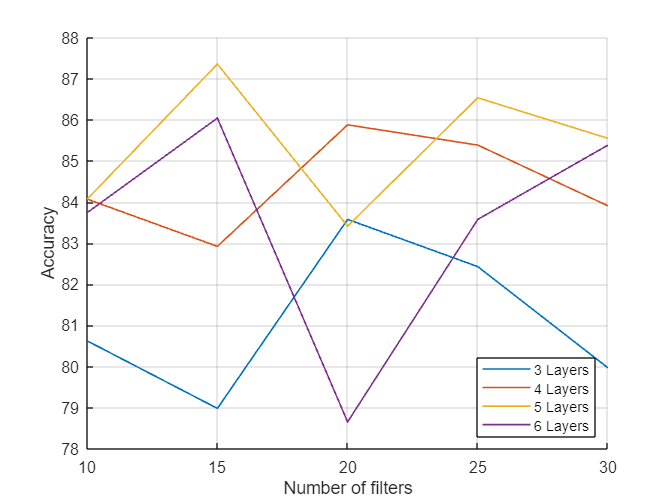

grid on
hold off
saveas(gcf, "GridlayerSearchFindings.png");

### 5.3 Use best hyperparameters from performing 'Grid Search' to train the network

gridsearch_layers = create_model(gridsearch_best_params, aux_params); % Create model from best hyperparameters (grid search)
tic; % Start timing before training
disp("Using the best parameters from performing grid search to train the final grid search network.")

Using the best parameters from performing grid search to train the final grid search network.


disp("Number of layers: " + gridsearch_best_params(1) + " | " + "Number of filters: " + gridsearch_best_params(2));

Number of layers: 5 | Number of filters: 15


Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:02 |       26.67% |       44.01% |       1.7337 |       1.4662 |          0.0020 |
|       1 |          10 |       00:00:04 |       80.00% |       68.14% |       0.6685 |       0.7840 |          0.0020 |
|       1 |          20 |       00:00:07 |       80.00% |       73.23% |       0.5535 |       0.6972 |          0.0020 |
|       1 |          30 |       00:00:09 |       93.33% |       81.12% |       0.4208 |   

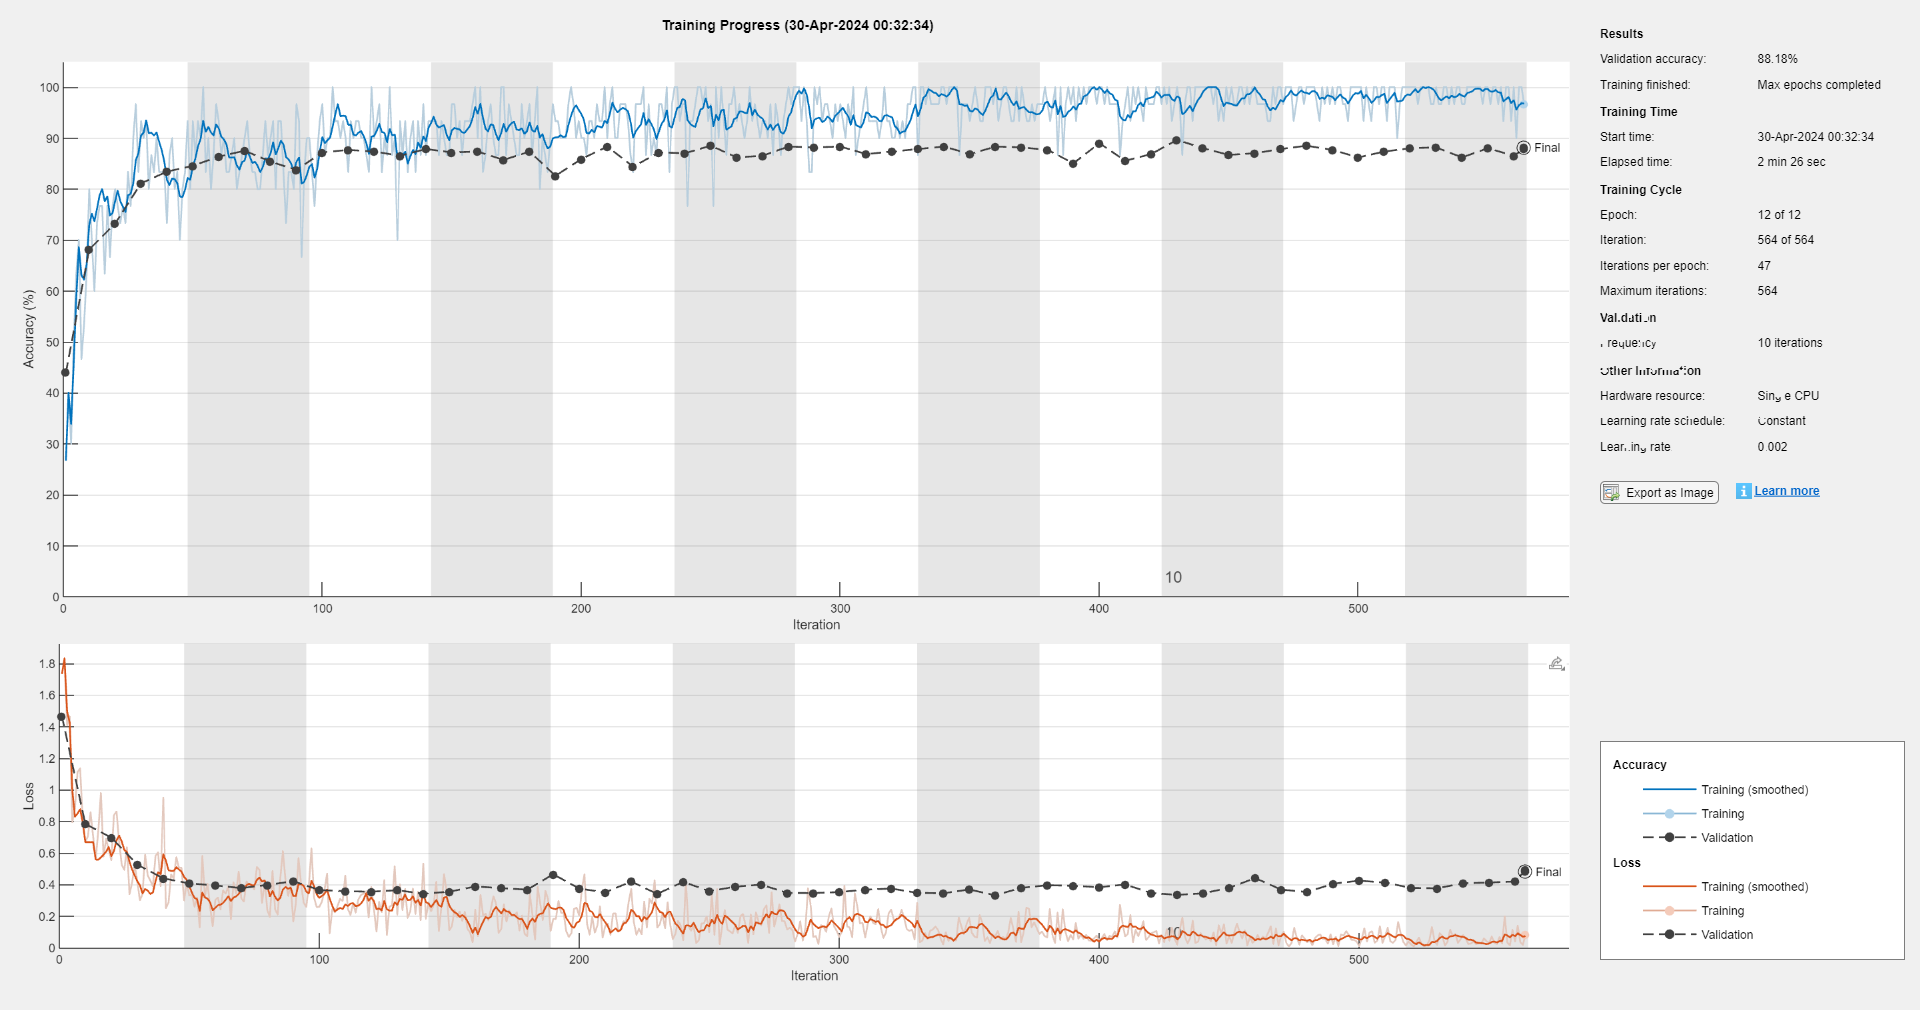

[gridsearch_model, gridsearch_model_info] = trainNetwork(imdsTrain_aug, gridsearch_layers, baseline_options); % Train model

gridsearch_training_time = toc; % Stop timer after training
clear tic;

### 5.4 Evaluate the best hyper parameters from performing 'Grid Search'

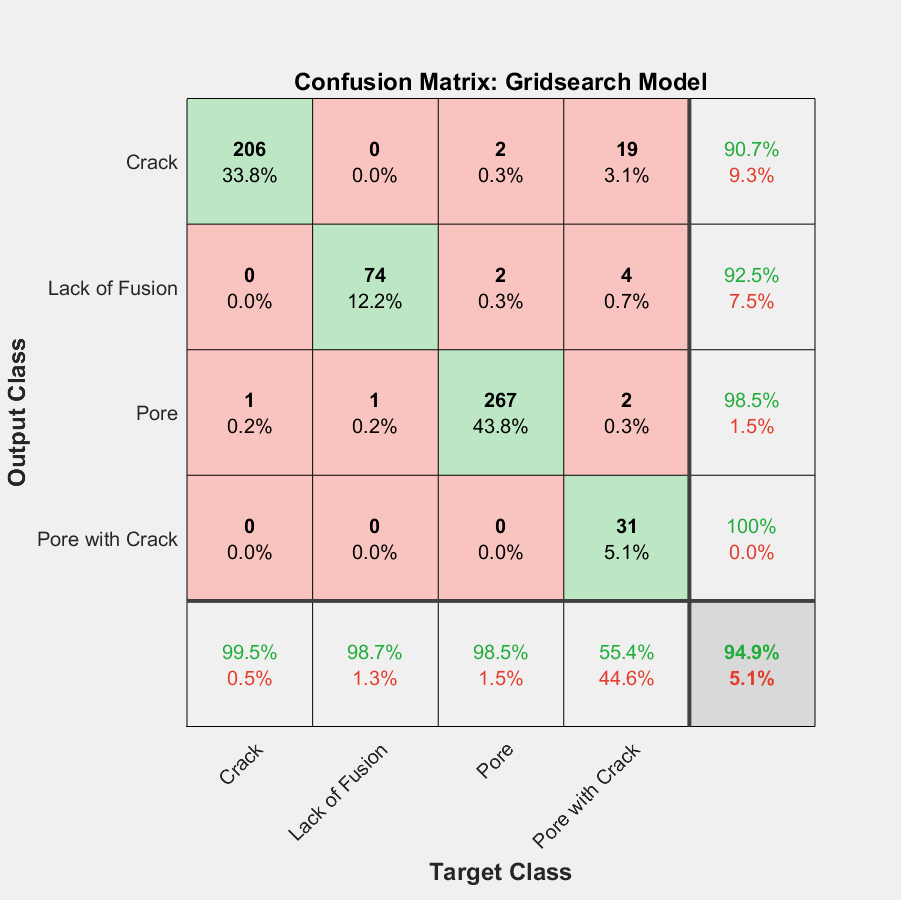

% Classify the validation output using the trained network
[gridsearch_YPred, ~] = classify(gridsearch_model, imdsVal_aug);

% Plot confusion matrix
figure;
plotconfusion(YVal, gridsearch_YPred);
title("Confusion Matrix: Gridsearch Model")

% saveas(gcf,['GridLayerSearch_OptimalTraining_6Layers_30Filters_Eval.png'])

## 6 Hyperparameter optimisation using Bayesian optimisation

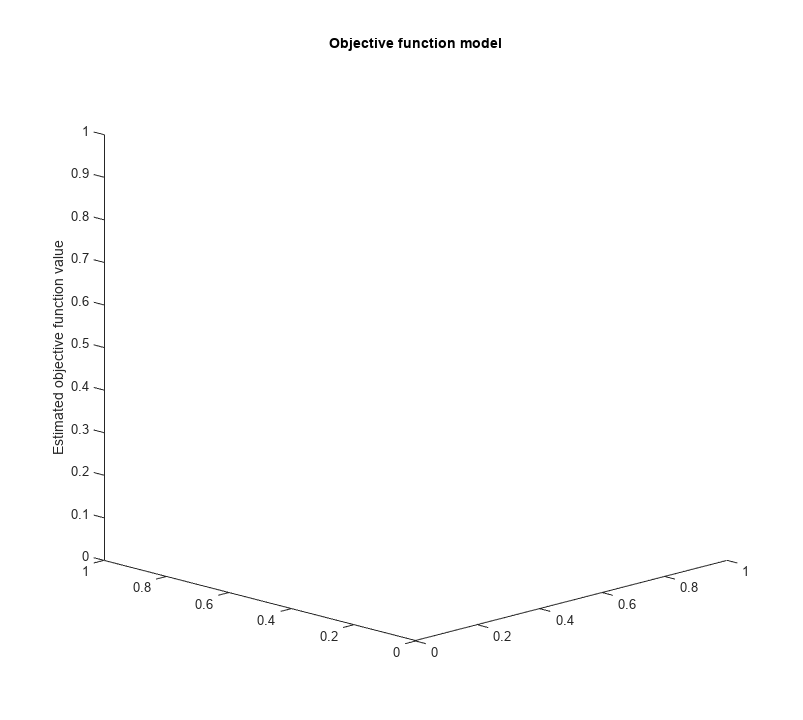

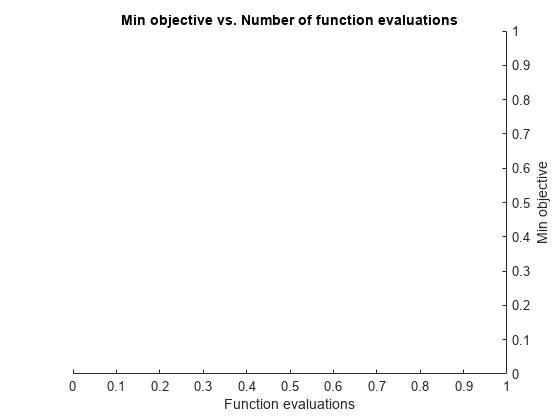

Training across multiple GPUs.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:19 |       20.00% |       52.92% |       3.6220 |       1.1025 |          0.0020 |
|       1 |          10 |       00:00:42 |       86.67% |       82.08% |       0.4929 |       0.8621 |          0.0020 |
|       1 |          20 |       00:01:05 |       83.33% |       81.74% |       0.4949 |       0.5054 |          0.0020 |
|       1 |          30 |       00:01:29 |       86.67% |       84.72% |       0.39

% select variables to optimise
optVars = [
    optimizableVariable('Layers',[3 7],'Type','integer')
    optimizableVariable('Filters',[10 40],'Type','integer')
    ];

% create the objective function, it trains a neural network and returns the
% classification error on the validation set
ObjFcn = makeObjFcn(imdsTrain_aug,imdsVal_aug,imdsVal.Labels,baseline_options,aux_params);


% Start timer
tic

% perform bayesian optimisation by minimising the classification error on
% the validation set
BayesObject = bayesopt(ObjFcn,optVars, ...
    'MaxTime',14*60*60, ...
    'IsObjectiveDeterministic',false, ...
    'UseParallel',false, ...
    'MaxObjectiveEvaluations',15);

bayesian_training_time = toc;
clear toc;

% load best network found in the optimisation
bestIdx = BayesObject.IndexOfMinimumTrace(end);
fileName = BayesObject.UserDataTrace{bestIdx}

fileName = "0.10016.mat"

fileName = "0.093596.mat"

fileName = "0.093596.mat"

bayesStruct = load(fileName)

bayesStruct = struct with fields:
               valError: 0.0936
             trainedNet: [1×1 SeriesNetwork]
    bayes_training_time: 226.0446
                options: [1×1 nnet.cnn.TrainingOptionsADAM]


### 6.1 Evaluate best hyperparameters from Bayesian Optimisation

% classify the validation output using the trained network
[bayes_YPred,~] = classify(bayesStruct.trainedNet,imdsal_aug);

% plot confusion matrix
figure;
plotconfusion(YVal,bayes_YPred)
title("Confusion Matrix: Bayesian Optimization")

% accuracy in percent
bayes_accuracy = 100*sum(bayes_YPred == YVal)/numel(YVal);
disp("Basyesian optimization network accuracy is: " + num2str(bayes_accuracy) + "%");

Basyesian optimization network accuracy is: 90.6404%


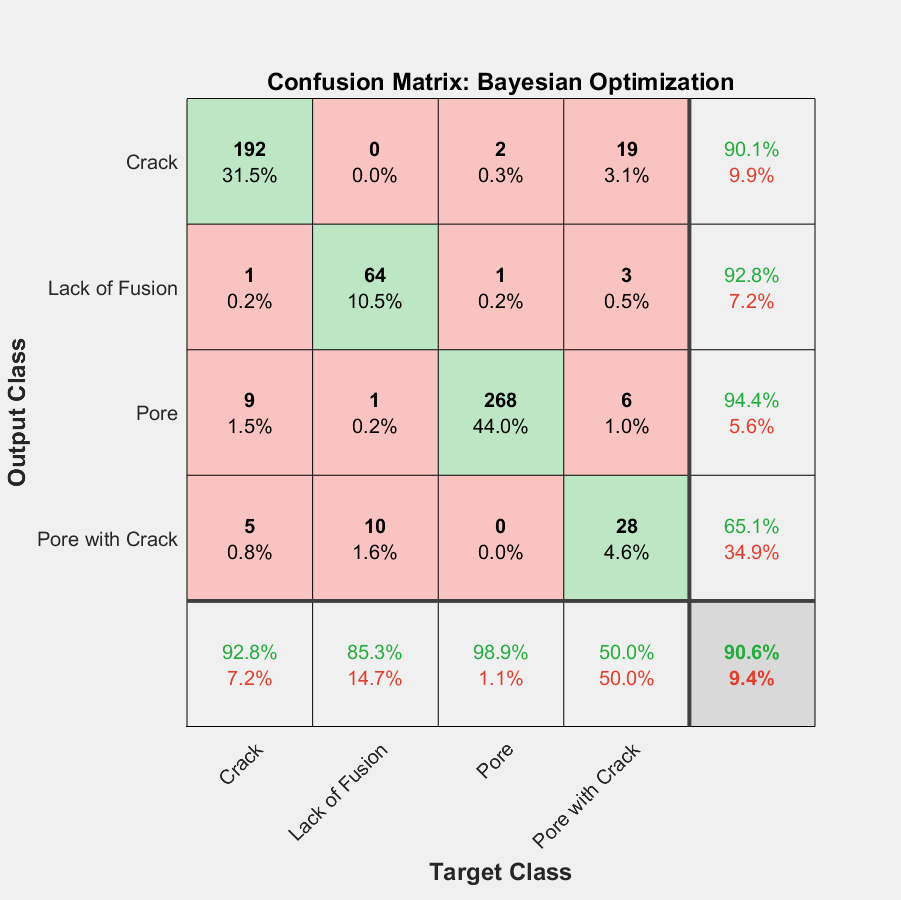

saveas(gcf, "BayesianOptimisation_Eval.png");

## Functions

function layers = create_model(hyper_params, aux_params)
    % Unpack hyperparameter values under test
    num_layers = hyper_params(1);
    num_filters = hyper_params(2);

    % Unpack auxiliary parameters needed to build network
    num_classes = aux_params{1};
    imageSize = aux_params{2};

    % create input layer
    layers = [
        imageInputLayer([imageSize 1])];

    % create blocks of conv -> batch norm -> relu -> max pool layers
    for i = 1:(num_layers-1)
        layers = [layers
            convolution2dLayer(3, num_filters, "Padding", "same")
            batchNormalizationLayer
            reluLayer
            maxPooling2dLayer(2,"Stride",2,"Padding","same")
        ];
    end

    % output layers
    layers = [layers
        
    convolution2dLayer(3, num_filters, "Padding", "same")
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer(2, "Stride", 1, "Padding", "same")
    
    fullyConnectedLayer(num_classes)
    softmaxLayer
    classificationLayer];
end

Bayesian Optimisation Function

function ObjFcn = makeObjFcn(dsTrain,dsVal,YVal_Pred,options,aux_params)
%OBJFCN objective function used in Bayesian Optimisation
ObjFcn = @valErrorFun;
    function [valError,cons,fileName] = valErrorFun(optVars)
        hyper_params = [optVars.Layers optVars.Filters];

        % create layers using the bayesian optimised hyperparameters
        layers = create_model(hyper_params,aux_params);
        
        tic;    % start the timer before training
        % train network
        trainedNet = trainNetwork(dsTrain,layers,options);
        close(findall(groot,'Tag','NNET_CNN_TRAININGPLOT_UIFIGURE'))
        bayes_training_time = toc;    % Stop the timer after training
        clear tic;

        % classify the validation output using the trained network
        [YPredicted,~] = classify(trainedNet,dsVal);

        % calculate the validation error
        valError = 1 - mean(YPredicted == YVal_Pred);
        
        % save the trained network as a '.mat' file using the validation
        % error as the filename
        fileName = num2str(valError) + ".mat";
        save(fileName,'trainedNet','valError','options',...
            'bayes_training_time');
        cons=[];
    end
end